# Design IIR Filter

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code creates a watermarked signal. For more information, see the *Generating Signals and Common Signal Operations* module.

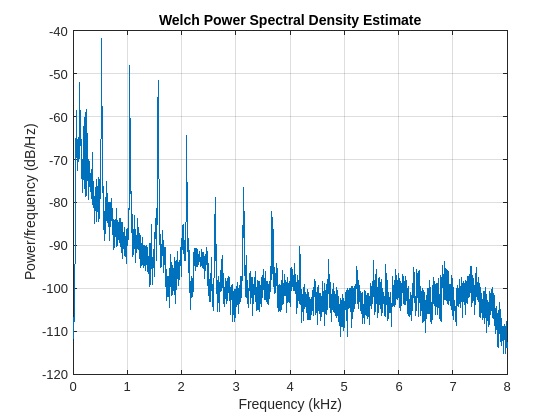

[flute,fs] = audioread("./data/NoisyFlute.wav");
flute = flute(1:3*fs);
t = ((0:numel(flute)-1)/fs)';
yin = chirp(t,2200,t(end),2500);
marked = flute + yin*0.0005;
pwelch(marked,[],[],[],fs)

## Tasks

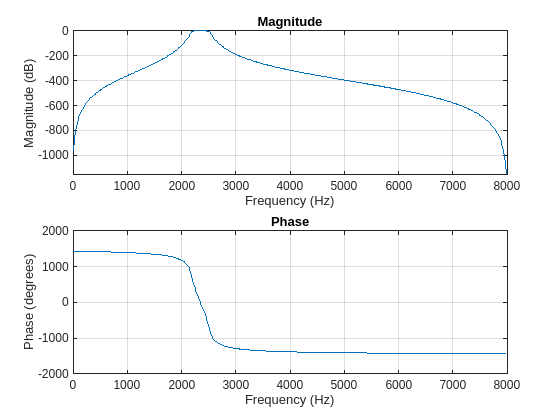

% Design a digital filter
designedFilter = designfilt('bandpassiir', ...
    'StopbandFrequency1',2100,'PassbandFrequency1',2200, ...
    'PassbandFrequency2',2500,'StopbandFrequency2',2600, ...
    'StopbandAttenuation1',60,'PassbandRipple',1, ...
    'StopbandAttenuation2',60,'SampleRate',fs);

% Visualize magnitude and phase responses
freqz(designedFilter.Coefficients,[],fs)

Visualize the spectrum of the filtered signal

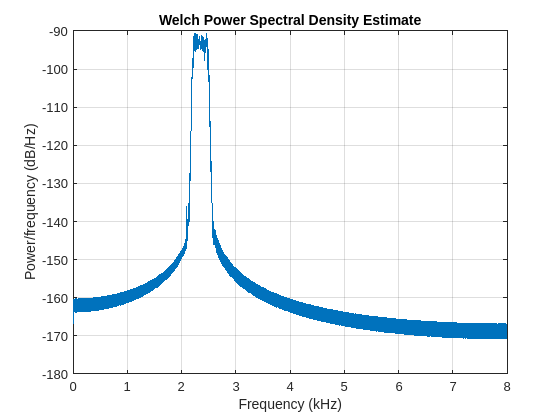

yout = filter(designedFilter,marked);
pwelch(yout,[],[],[],fs)